3. Explain how the FFT is used in de-noising. Illustrate your point via a specific example (different than code I have provided for you).

By taking the DFT of a noised signal f ,


$$\left\lbrack \begin{array}{c}
\hat{f_0 } \\
\hat{f_1 } \\
\hat{f_2 } \\
\hat{f_3 } \\
\vdots \\
\hat{f_{N-1} } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
1 & 1 & 1 & 1 & \cdots  & 1\\
1 & \omega_N  & \omega_N^2  & \omega_N^3  & \cdots  & \omega_N^{N-1} \\
1 & \omega_N^2  & \omega_N^4  & \omega_N^6  & \cdots  & \omega_N^{2\left(N-1\right)} \\
1 & \omega_N^3  & \omega_N  & \omega_N  & \cdots  & \omega_N^{3\left(N-1\right)} \\
\vdots  & \vdots  & \vdots  & \vdots  & \ddots  & \vdots \\
1 & \omega_N^{N-1}  & \omega_N^{2\left(N-1\right)}  & \omega_N^{3\left(N-1\right)}  & \cdots  & \omega_N^{{\left(N-1\right)}^2 } 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
f_0 \\
f_1 \\
f_2 \\
f_3 \\
\vdots \\
f_{N-1} 
\end{array}\right\rbrack$$


$\hat{f}$is a complex vector

In order to get norm we will take $\hat{f}$multipy its conjugate


$$\mathrm{spectrum}=\frac{\hat{f} \cdot \overline{\hat{f} } }{N}$$


Then we will get spectrum of f

Then we need to set up a threshold and apply to the spectrum we have.

Then the spectrum that less than the threshold will be filtered.

Then we can filter out the noise signal according to the threshold and spectrum we got before.

Then take the iDFT to the filtered back the signal.

For example

clear
dx=0.001;
x=0:dx:1;

Take the sum of cosine with three frequency

33 66 and 100

f=cos(2*33*x*pi)+cos(2*66*x*pi)+cos(2*100*x*pi);

Then add some noise

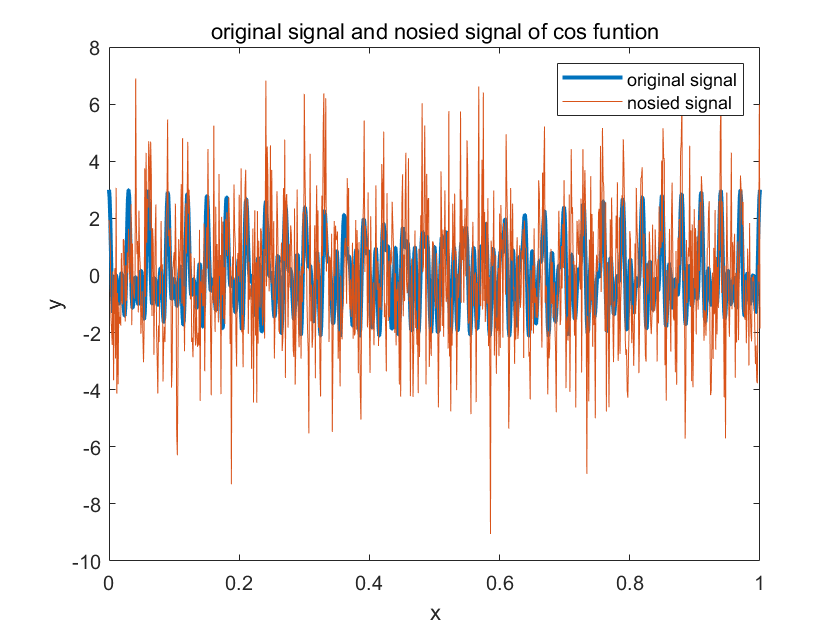

f_noisy=f+2*randn(size(x));

%plot
plot(x,f,'LineWidth',2)
hold on
plot(x,f_noisy)
ylabel('y')
xlabel('x')
legend('original signal','nosied signal')
title('original signal and nosied signal of cos funtion')
hold off

here we take the DFT of both original and noise

N=length(x);
F=fft(f,N);
F_noisy=fft(f_noisy);

And compute the power spectral density

psd=F.*conj(F)/N;
psd_noisy=F_noisy.*conj(F_noisy)/N;

Set the frequecy axis

Since the psd is center symmetric, we only need half of the frequecy axis

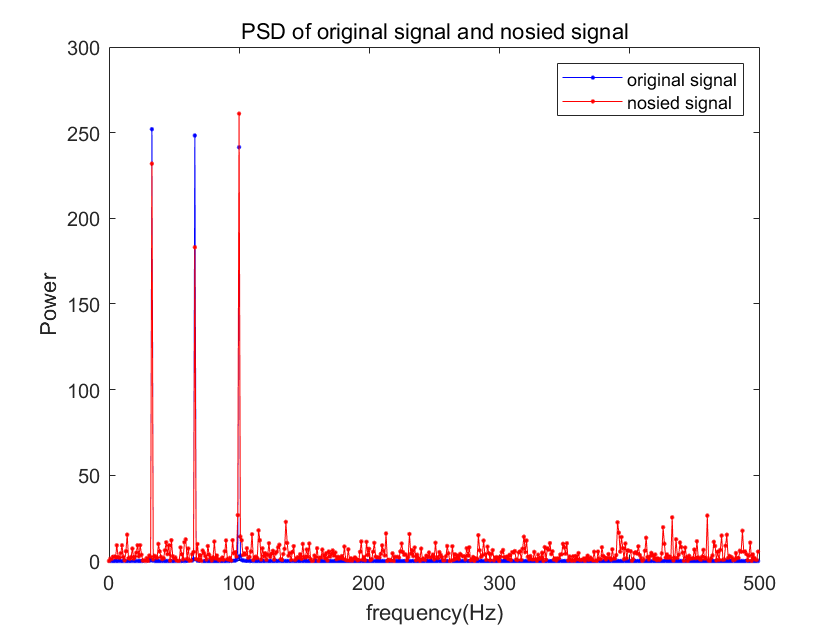

freq_axis=1/(dx*N)*[0:N-1];
axis_half=1:floor(N/2);

%plot of the spectrum 
plot(freq_axis(axis_half),psd(axis_half),'.-b')
hold on
plot(freq_axis(axis_half),psd_noisy(axis_half),'.-r')
xlabel('frequency(Hz)')
ylabel('Power')
legend('original signal','nosied signal')
title('PSD of original signal and nosied signal')
hold off

Set threshold=50 and filter out the spectrum less than 50.

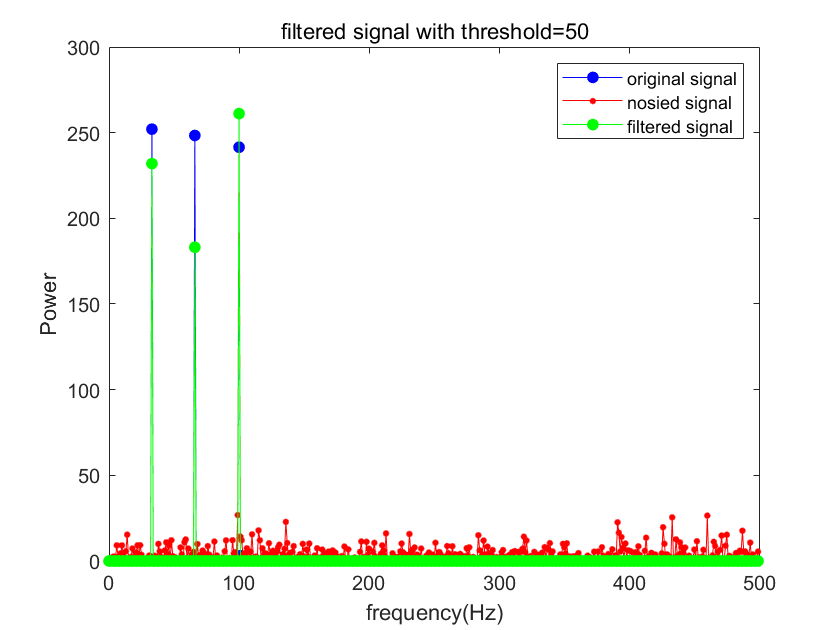

inds_filter=psd_noisy>50;%return bool
psd_filter=psd_noisy.*inds_filter;

plot(freq_axis(axis_half),psd(axis_half),'.-b','MarkerSize',20)
hold on
plot(freq_axis(axis_half),psd_noisy(axis_half),'.-r','MarkerSize',10)
plot(freq_axis(axis_half),psd_filter(axis_half),'.-g','MarkerSize',20)
xlabel('frequency(Hz)')
ylabel('Power')
legend('original signal','nosied signal','filtered signal')
title('filtered signal with threshold=50')
hold off

from the plot we can see the filtered signal only has three peek.

Then we need to take iDFT of the filtered spectrum back to the signal

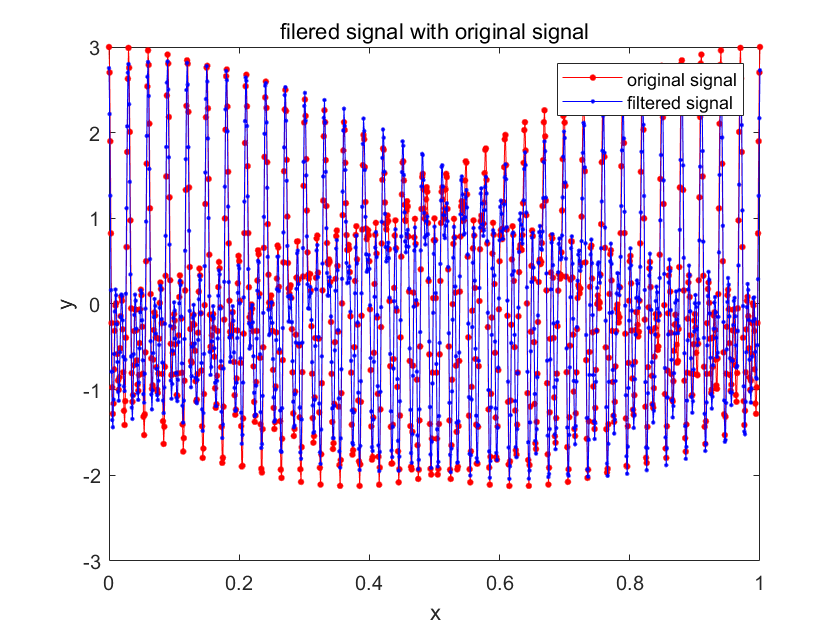

F_filter=F_noisy.*inds_filter;%filter out the noied according to the threshold
f_filter=ifft(F_filter);%iDFT

plot(x,f,'.-r','MarkerSize',10)
hold on
plot(x,f_filter,'.-b')
xlabel('x')
ylabel('y')
legend('original signal','filtered signal')
title('filered signal with original signal')
hold off

and we can also compute the percentage error

Sum_f=sum(abs(f))

Sum_f = 1.0004e+03

error=sum(abs((f(:)-f_filter(:))))

error = 204.4907

percentage_error=error/Sum_f

percentage_error = 0.2044